Apartado 1

Ka = -1.6000;
Kb = 8;
K3 = 0.7000;
K2 = 8;
K1 = 22;
K0 = 0;
Kw = 3.4000;
Ks = 0.1000;
ts = 1;
T = 0.1;

Apartado 2

s = zpk('s');
G = (Ka*s+Kb)/(K3*s^3+K2*s^2+K1*s+K0)

G =
 
      -2.2857 (s-5)
  ---------------------
  s (s+6.821) (s+4.608)
 
Continuous-time zero/pole/gain model.
Model Properties


Apartado 3

Gz = c2d(G, T, 'zoh')

Gz =
 
  -0.0064445 (z+0.5832) (z-1.651)
  -------------------------------
    (z-1) (z-0.6308) (z-0.5056)
 
Sample time: 0.1 seconds
Discrete-time zero/pole/gain model.
Model Properties


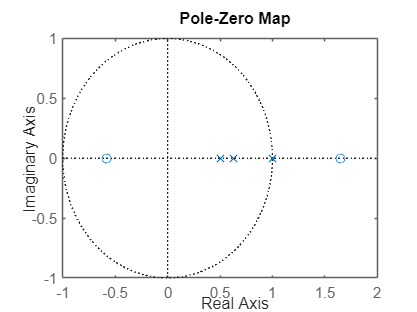

pzmap(Gz)

El sistema es de orden 3 debido a que el grado del denominador máximo es 3

El sistema es de tipo 1 debido a que eso viene definido por la cantidad de polos en z = 1

Apartado 4

- Primero he usado un comando de matlab para obtener las matrices del espacio de estados, solo para ver como podría ser el resultado, sin embargo, se que puede haber más de una solución, por lo que presento las ecuaciones que me ayudan a obtener el espacio de estados.

[A, B, C, D]=tf2ss([Ka Kb], [K3 K2 K1 K0])

A =   -11.4286  -31.4286         0
    1.0000         0         0
         0    1.0000         0


B =      1
     0
     0


C =          0   -2.2857   11.4286


D = 0

- Ahora lo hacemos a la vieja usanza; como tenemos la función de transferencia, pasamos el denominador de la función de transferencia a la izquierda multiplicando a θ(s) y pasamos δ(s) a la derecha. Aplicando despues la transformada inversa de laplace, más concretamente la propiedad de las derivadas. (Recalco que considero las condiciones iniciales iguales a 0)

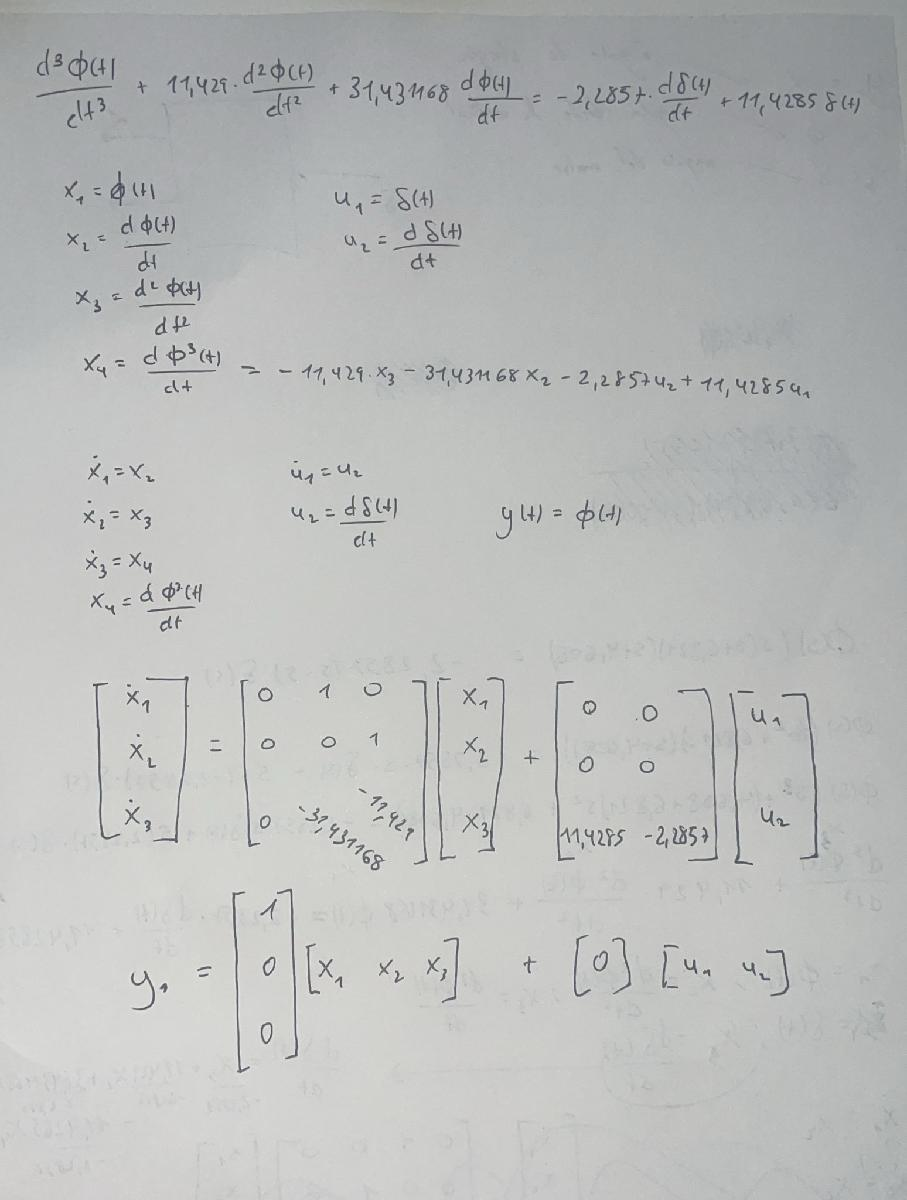

Apartado 5

Escalón aplicado a la parte continua:

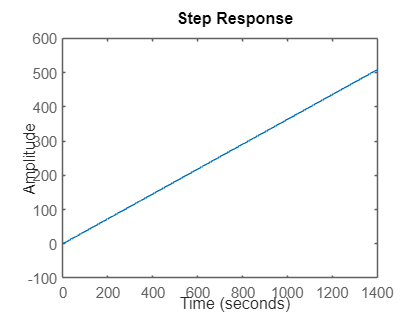

figure
step(G)

Vemos que hace una pendiente más o menos lineal, esto es debido al polo en s = 0, el cual hace que estemos al borde de la estabilidad y encima es un integrador, lo cual hace que tengamos esta pendiente que parece que es inestable.

Escalón aplicado a la parte discreta

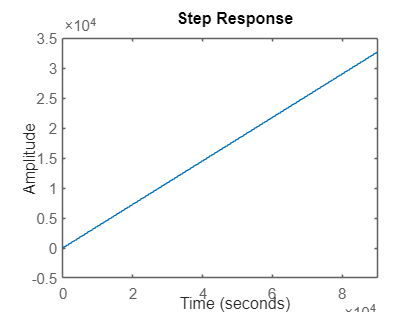

figure
step(Gz)